# MTE 546 Data Accquisition Code

University of Waterloo MTE 546 Written by Eugene Li Dec 2019 Updated by Lyndon Tang Jan 2025

close all; clear all; clc;

## Device Configuration

If this is operating correctly the board name should appear

devices = daq.getDevices

devices = ni: National Instruments(TM) NI ELVIS II+ (Device ID: 'Dev1')
   Analog input supports:
      7 ranges supported
      Rates from 0.1 to 1250000.0 scans/sec
      16 channels ('ai0' - 'ai15')
      'Voltage' measurement type
   
   Analog output supports:
      -5.0 to +5.0 Volts,-10 to +10 Volts ranges
      Rates from 0.1 to 2857142.9 scans/sec
      2 channels ('ao0','ao1')
      'Voltage' measurement type
   
   Digital IO supports:
      Rates from 0.1 to 1000000.0 scans/sec
      39 channels ('port0/line0' - 'port2/line6')
      'InputOnly','OutputOnly','Bidirectional' measurement types
   
   Counter input supports:
      Rates from 0.1 to 80000000.0 scans/sec
      2 channels ('ctr0','ctr1')
      'EdgeCount','PulseWidth','Frequency','Position' measurement types
   
   Counter output supports:
      Rates from 0.1 to 80000000.0 scans/sec
      2 channels ('ctr0','ctr1')
      'PulseGeneration' measurement type
   



s = daq.createSession('ni');

% Add analog inputs for each sensor being read
% 'Dev1' corresponds to the ELVIS board
% Each channel 0, 1 corresponds to the analog input on the ELVIS
addAnalogInputChannel(s, 'Dev1', 0, 'Voltage') % Long x

ans =     'Data acquisition session using National Instruments(TM) hardware:
        Will run for 1 second (1000 scans) at 1000 scans/second.
        Number of channels: 1
           index Type Device Channel MeasurementType      Range       Name
           ----- ---- ------ ------- --------------- ---------------- ----
           1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
        
     Methods, Events .'


addAnalogInputChannel(s, 'Dev1', 1, 'Voltage') % Medium x

ans =     'Data acquisition session using National Instruments(TM) hardware:
        Will run for 1 second (1000 scans) at 1000 scans/second.
        Number of channels: 2
           index Type Device Channel MeasurementType      Range       Name
           ----- ---- ------ ------- --------------- ---------------- ----
           1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
           2     ai   Dev1   ai1     Voltage (Diff)  -10 to +10 Volts
        
     Methods, Events .'


addAnalogInputChannel(s, 'Dev1', 2, 'Voltage') % Small y

ans =     'Data acquisition session using National Instruments(TM) hardware:
        Will run for 1 second (1000 scans) at 1000 scans/second.
        Number of channels: 3
           index Type Device Channel MeasurementType      Range       Name
           ----- ---- ------ ------- --------------- ---------------- ----
           1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
           2     ai   Dev1   ai1     Voltage (Diff)  -10 to +10 Volts
           3     ai   Dev1   ai2     Voltage (Diff)  -10 to +10 Volts
        
     Methods, Events .'


addAnalogInputChannel(s, 'Dev1', 3, 'Voltage') % Long y

ans =     'Data acquisition session using National Instruments(TM) hardware:
        Will run for 1 second (1000 scans) at 1000 scans/second.
        Number of channels: 4
           index Type Device Channel MeasurementType      Range       Name
           ----- ---- ------ ------- --------------- ---------------- ----
           1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
           2     ai   Dev1   ai1     Voltage (Diff)  -10 to +10 Volts
           3     ai   Dev1   ai2     Voltage (Diff)  -10 to +10 Volts
           4     ai   Dev1   ai3     Voltage (Diff)  -10 to +10 Volts
        
     Methods, Events .'




addAnalogInputChannel(s, 'Dev1', 4, 'Voltage') % therm (0, 1)

ans =     'Data acquisition session using National Instruments(TM) hardware:
        Will run for 1 second (1000 scans) at 1000 scans/second.
        Number of channels: 5
           index Type Device Channel MeasurementType      Range       Name
           ----- ---- ------ ------- --------------- ---------------- ----
           1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
           2     ai   Dev1   ai1     Voltage (Diff)  -10 to +10 Volts
           3     ai   Dev1   ai2     Voltage (Diff)  -10 to +10 Volts
           4     ai   Dev1   ai3     Voltage (Diff)  -10 to +10 Volts
           5     ai   Dev1   ai4     Voltage (Diff)  -10 to +10 Volts
        
     Methods, Events .'


addAnalogInputChannel(s, 'Dev1', 5, 'Voltage') % therm (1, 1)

ans =     'Data acquisition session using National Instruments(TM) hardware:
        Will run for 1 second (1000 scans) at 1000 scans/second.
        Number of channels: 6
           index Type Device Channel MeasurementType      Range       Name
           ----- ---- ------ ------- --------------- ---------------- ----
           1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
           2     ai   Dev1   ai1     Voltage (Diff)  -10 to +10 Volts
           3     ai   Dev1   ai2     Voltage (Diff)  -10 to +10 Volts
           4     ai   Dev1   ai3     Voltage (Diff)  -10 to +10 Volts
           5     ai   Dev1   ai4     Voltage (Diff)  -10 to +10 Volts
           6     ai   Dev1   ai5     Voltage (Diff)  -10 to +10 Volts
        
     Methods, Events .'


addAnalogInputChannel(s, 'Dev1', 6, 'Voltage') % therm (0, 0)

ans =     'Data acquisition session using National Instruments(TM) hardware:
        Will run for 1 second (1000 scans) at 1000 scans/second.
        Number of channels: 7
           index Type Device Channel MeasurementType      Range       Name
           ----- ---- ------ ------- --------------- ---------------- ----
           1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
           2     ai   Dev1   ai1     Voltage (Diff)  -10 to +10 Volts
           3     ai   Dev1   ai2     Voltage (Diff)  -10 to +10 Volts
           4     ai   Dev1   ai3     Voltage (Diff)  -10 to +10 Volts
           5     ai   Dev1   ai4     Voltage (Diff)  -10 to +10 Volts
           6     ai   Dev1   ai5     Voltage (Diff)  -10 to +10 Volts
           7     ai   Dev1   ai6     Voltage (Diff)  -10 to +10 Volts
        
     Methods, Events .'


addAnalogInputChannel(s, 'Dev1', 7, 'Voltage') % therm (1, 0)

ans =     'Data acquisition session using National Instruments(TM) hardware:
        Will run for 1 second (1000 scans) at 1000 scans/second.
        Number of channels: 8
           index Type Device Channel MeasurementType      Range       Name
           ----- ---- ------ ------- --------------- ---------------- ----
           1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
           2     ai   Dev1   ai1     Voltage (Diff)  -10 to +10 Volts
           3     ai   Dev1   ai2     Voltage (Diff)  -10 to +10 Volts
           4     ai   Dev1   ai3     Voltage (Diff)  -10 to +10 Volts
           5     ai   Dev1   ai4     Voltage (Diff)  -10 to +10 Volts
           6     ai   Dev1   ai5     Voltage (Diff)  -10 to +10 Volts
           7     ai   Dev1   ai6     Voltage (Diff)  -10 to +10 Volts
           8     ai   Dev1   ai7     Voltage (Diff)  -10 to +10 Volts
        
     Methods, Events

## TODO: Set the sample rate

Set the sample rate by replacing 'nan' with the desired rate in Hz

sample_rate = validate_sample_rate(1000);

Sample rate: 1000.00 Hz


s.Rate = sample_rate;

% Normal Operation
% Read for a set period of time
s.DurationInSeconds = 5;

fprintf("Measurement Started");

Measurement Started

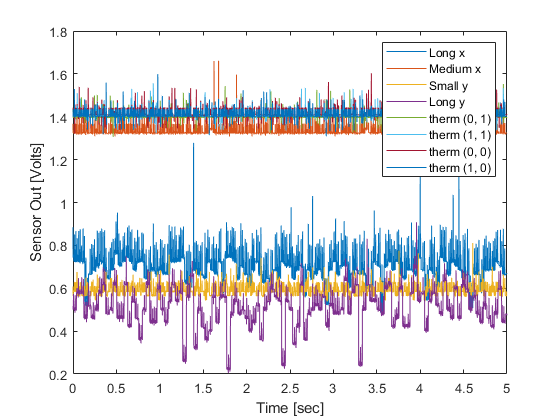

[data, time] = s.startForeground;

figure;
plot(time, data);
xlabel('Time [sec]');
ylabel('Sensor Out [Volts]');
legend('Long x', 'Medium x', 'Small y', 'Long y', 'therm (0, 1)', 'therm (1, 1)', 'therm (0, 0)', 'therm (1, 0)');

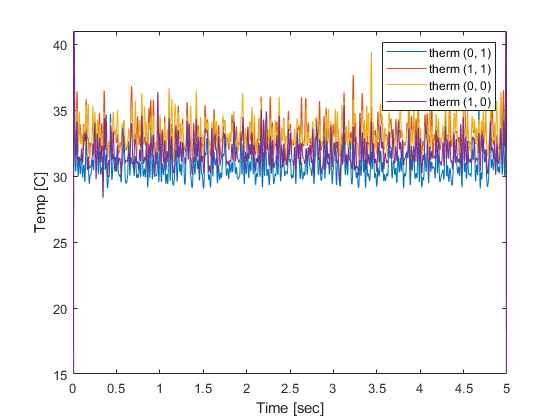

%save("2p1_5.mat", "time", "data")
figure;
temp = (lowpass(data(:,5:end),0.1,1000) - 1.25)/0.005;
plot(time, temp);
ylim([15 41])
xlabel('Time [sec]');
ylabel('Temp [C]');
legend('therm (0, 1)', 'therm (1, 1)', 'therm (0, 0)', 'therm (1, 0)')

## TODO: Save 'data', 'time' to a file

help save;

 save Save workspace variables to file. 
    save(FILENAME) stores all variables from the current workspace in a
    MATLAB formatted binary file (MAT-file) called FILENAME. Specify 
    FILENAME as a character vector or a string scalar. For example, specify
    FILENAME as 'myFile.mat' or "myFile.mat".
 
    save(FILENAME,VARIABLES) stores only the specified variables. Specify 
    FILENAME and VARIABLES as character vectors or string scalars.
 
    save(FILENAME,'-struct',STRUCTNAME,FIELDNAMES) stores the fields of the
    specified scalar structure as individual variables in the file. If you 
    include the optional FIELDNAMES, the save function stores only the
    specified fields of the structure.  You cannot specify VARIABLES and 
    the '-struct' keyword in the same call to save.
 
    save(FILENAME, ..., '-append') adds new variables to an existing file.
    

## Alternative Read Modes

%{
% Debugging Single-shot Read 
data = s.inputSingleScan;

% Continuous Background Read
figure;
s.DurationInSeconds = 5;
lh = addlistener(s, 'DataAvailable', @(src, event) plot(event.TimeStamps, event.Data));
s.NotifyWhenDataAvailableExceeds = 8000;
s.startBackground();
s.wait();
delete(lh);
%}


function sample_rate = validate_sample_rate(sample_rate)
assert(isequal(size(sample_rate), size(1)), 'Sample rate must be a scalar');
assert(~isnan(sample_rate), 'Sample rate was not set. Choose a sample rate');
assert((isfloat(sample_rate) && ~isinf(sample_rate)) || isinteger(sample_rate), 'Sample rate must be a number');
assert(sample_rate > 0, 'Sample rate must be positive');
fprintf('Sample rate: %.2f Hz\n', sample_rate);
end